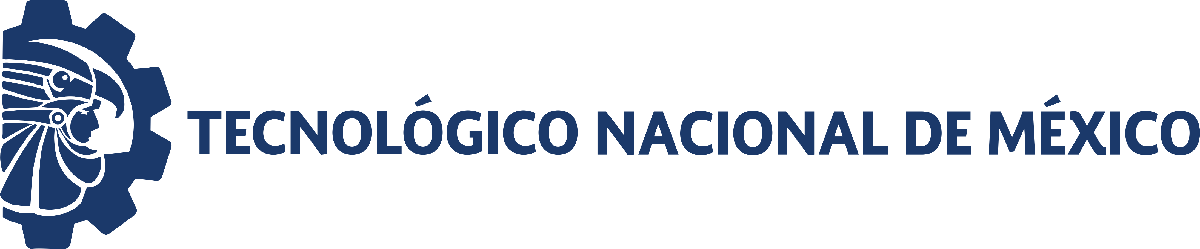                                 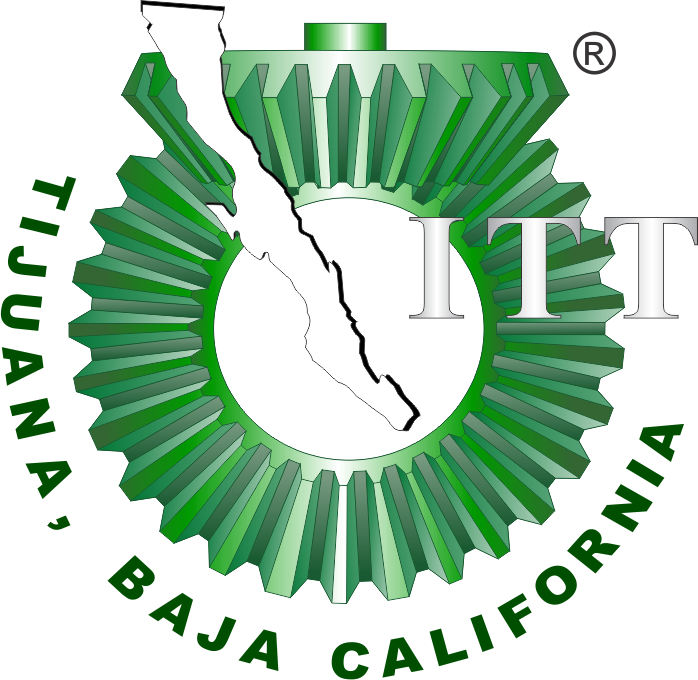

# Práctica Tres: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[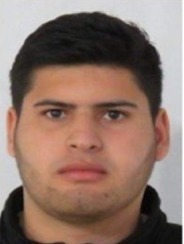]

Nombre del alumno: Jesus Javier Morales Lozoya

Número de control: 20210806

Correo institucional: **jesus.moralesl201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

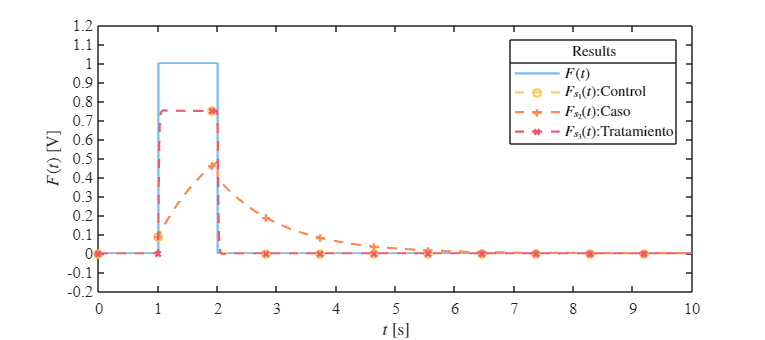

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema_Pra_3';
open_system(file);

in = Simulink.SimulationInput(file);
in = setModelParameter(in,'StopTime',tend);
in = setModelParameter(in,'Solver','ode23t');
in = setModelParameter(in,'MaxStep','1e-3');
x = sim(in);
plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3,'Lazo Cerrado')

## Lazo abierto

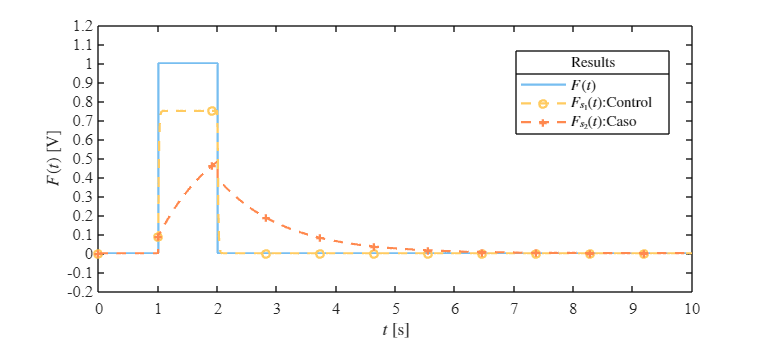

x1 = sim(in);
plotsignals(x1.t, x1.F, x1.Fs1, x1.Fs2, [], 'Lazo abierto');

 **Función: Respuesta a las señales **

function plotsignals(t,  F, Fs1, Fs2, Fs3, nombre)
       % Convertir timeseries a vectores si es necesario
   if isa(F,'timeseries'),  F = F.Data;   end
   if isa(Fs1,'timeseries'), Fs1 = Fs1.Data; end
   if isa(Fs2,'timeseries'), Fs2 = Fs2.Data; end
   if isa(Fs3,'timeseries'), Fs3 = Fs3.Data; end
   

   % Asegurar formato vector columna (1D)
   F = F(:);
   Fs1 = Fs1(:);
   Fs2 = Fs2(:);
   Fs3 = Fs3(:);
   

   % Crear figura
   set(figure(),'Color','w')
   set(gcf,'units','centimeters','position',[1,1,18,8])
   set(gca,'FontName','Times New Roman','FontSize',11)
   hold on; grid off; box on;

    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50]/255;
    colororder(mycolors)

    vars = {F, Fs1, Fs2, Fs3};
    labels = {'$F(t)$', ...
              '$F_{s_1}(t)$:Control', ...
              '$F_{s_2}(t)$:Caso', ...
              '$F_{s_3}(t)$:Tratamiento'};
    estilos = {'-', '--o', '--+', '--x'};

    p = [];
    for i = 1:length(vars)
        if ~isempty(vars{i})
            p(end+1) = plot(t, vars{i}, estilos{i}, 'LineWidth', 1.5, ...
                'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
        end
    end

    if length(p) >= 5
        set(p(5),'LineWidth',3);
    end

    L = legend(p, labels{1:length(p)}, 'Interpreter', 'Latex', ...
        'FontSize', 10, 'Location', 'Best', 'Box', 'On');
    title(L, 'Results', 'FontSize', 10);

    xlabel('$t$ [s]', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$F(t)$ [V]', 'Interpreter', 'Latex', 'FontSize', 11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2);

     exportgraphics(gcf, [nombre '.pdf'], 'ContentType', 'vector');
    exportgraphics(gcf, [nombre '.png'], 'ContentType', 'vector');
end